Chapter 8

% DC gain
% Transfer eqn: 20/(s^2+10*s+11)
clc;clear;
syms s
G=@(s) 20/(s^2+10*s+11);
DC_gain=limit(G(s),s,0);
fprintf('DC gain: %f\n',DC_gain)

DC gain: 1.818182


%% Intial value problem
% Transfer eqn: (2 + 6*s + 2*s^2)/(2*s*(s+2)^2)
clc;clear;
syms s
G=@(s) (2 + 6*s + 2*s^2)/(2*s*(s+2)^2);
Initial_val=limit(s*G(s),s,Inf);
fprintf('Inital value: %.3f\n',Initial_val);

Inital value: 1.000


%% Final value problem
% Transfer function: (2 + 6*s + 2*s^2)/(2*s*(s+2)^2)
clc;clear;
syms s
G=@(s) (2 + 6*s + 2*s^2)/(2*s*(s+2)^2);
Final_val=limit(s*G(s),s,0);
fprintf('Final value: %.3f\n',Final_val);

Final value: 0.250


%% Poles/zeros
% Transfer function: (s+50)/(s^2+11s+12)
clc;clear;
G=tf([1 50],[1 11 12]);
disp('Transfer function:')

Transfer function:


G

G =
 
      s + 50
  ---------------
  s^2 + 11 s + 12
 
Continuous-time transfer function.



poles=pole(G)

poles =    -9.7720
   -1.2280


zeros=zero(G)

zeros = -50

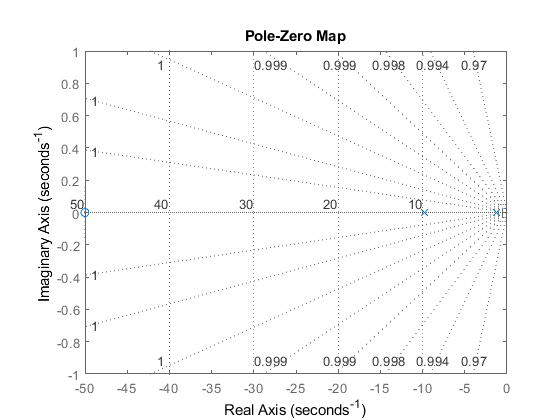

% Pole-zero map
pzmap(G)
grid on

%% Differential equation
% 3*y'''(t) + 2*y''(t) + 3y(t) = 1
% Initial condition: y(0)=0;y'(0)=0;y''(0)=1;
% Laplace Transform
clc;clear;
syms s Y
y0=0;dy0=0;dy20=1;
Y1=@(s) s*Y-y0;
Y2=@(s) s^2*Y-s*y0-dy0;
Y3=@(s) s^3*Y-s^2*y0-s*dy0-dy20;
eqn=3*Y3(s)+2*Y2(s)+3*Y-laplace(1,s);
solve(eqn,Y)

$$ans = \frac{\frac{1}{s}+3}{3\,s^{3}+2\,s^{2}+3}$$

%% Differential equation solve using Laplace transform
% 3*y'''(t) + 2*y''(t) + 3y(t) = 1
% Initial condition: y(0)=0;y'(0)=0;y''(0)=1;
clc;clear;
syms s Y
% Initial conditions
y0=0;dy0=0;dy20=1;
Y1=@(s) s*Y-y0;
Y2=@(s) s^2*Y-s*y0-dy0;
Y3=@(s) s^3*Y-s^2*y0-s*dy0-dy20;
% Differential equation
eqn=3*Y3(s)+2*Y2(s)+3*Y-laplace(1,s);
solve(eqn,Y)

$$ans = \frac{\frac{1}{s}+3}{3\,s^{3}+2\,s^{2}+3}$$

% 2s^2+4s+1/s^2+2s
clc;clear;
syms s
b = [2 4 1];
a = [1 2 0];
[r,p,k] = residue(b,a)

r =    -0.5000
    0.5000


p =     -2
     0


k = 2

Expansion=@(s) r(1)/(s-p(1)) + r(2)/(s-p(2)) + k;
Expansion(s)

$$ans = \frac{1}{2\,s}-\frac{1}{2\,\left(s+2\right)}+2$$

%% Partial fraction
% Fraction: (2s+3)/(s^2+2s)
% Highest degree of Numerator < Highest degree of denominator
clc;clear;
syms s
b = [2 3];
a = [1 2 0];
disp('The residuals:')

The residuals:


[r,p,k] = residue(b,a)

r =     0.5000
    1.5000


p =     -2
     0



k =

     []



Expan=@(s) r(1)/(s-p(1)) + r(2)/(s-p(2));
disp('The partial fraction expansion:')

The partial fraction expansion:


disp(Expan(s))

$$\frac{1}{2\,\left(s+2\right)}+\frac{3}{2\,s}$$

%% Partial fraction-2
% Fraction:(2s^2+4s+1)/(s^2+2s)
% Highest degree of Numerator = Highest degree of denominator
clc;clear;
syms s
b = [2 4 1];
a = [1 2 0];
disp('The residuals:')

The residuals:


[r,p,k] = residue(b,a)

r =    -0.5000
    0.5000


p =     -2
     0


k = 2

Expansion=@(s) r(1)/(s-p(1)) + r(2)/(s-p(2)) + k;
disp('The partial fraction expansion:')

The partial fraction expansion:


disp(Expansion(s))

$$\frac{1}{2\,s}-\frac{1}{2\,\left(s+2\right)}+2$$

%% Partial fraction-3
% Fraction: (2s^3+4s^2+3s+2)/(s^2+2s+1)
% Highest degree of Numerator > Highest degree of denominator
clc;clear;
syms s
b = [2 4 3 3];
a = [1 2 1];
disp('The residuals:')

The residuals:


[r,p,k] = residue(b,a)

r =      1
     2


p =     -1
    -1


k =      2     0


Expansion=@(s) r(1)/(s-p(1)) + r(2)/(s-p(2)) + (s*k(1)+k(2));
disp('The partial fraction expansion:')

The partial fraction expansion:


disp(Expansion(s))

$$2\,s+\frac{3}{s+1}$$

%% Partial fraction-3
% Fraction:(2s^2+2s+1)/(2s^2+4s+3)
% Highest degree of Numerator = Highest degree of denominator
clc;clear;
syms s
N = [2 2 1];
D = [2 4 3];
disp('The residuals:')

The residuals:


[r,p,k] = residue(N,D)

r =    -0.5000
   -0.5000


p =   -1.0000 + 0.7071i
  -1.0000 - 0.7071i


k = 1

Expansion=@(s) r(1)/(s-p(1)) + r(2)/(s-p(2)) + k;
disp('The partial fraction expansion:')

The partial fraction expansion:


disp(Expansion(s))

$$1-\frac{1}{2\,\left(s+1+\frac{\sqrt{2}\,\mathrm{i}}{2}\right)}-\frac{1}{2\,\left(s+1-\frac{\sqrt{2}\,\mathrm{i}}{2}\right)}$$

%% Negative damped system : Zeta=-2
clc;clear;
K=2;
omega_n=5;
zeta=-2;
s=tf('s');
disp('Transfer function:')
G=(K*omega_n^2)/(s^2+2*zeta*omega_n*s+omega_n^2)
step(G);
grid on;
xlim([0 0.25]);
ylim([-0.5 2.5]);
disp('Parameters:')
disp(stepinfo(G))
% Pole-zero map
figure(2);
pzmap(G)
grid on